# Linear Control Design II - Group Work Problem Module 8

## Description

**Problem 1** Solve Problem 2.10 from the textbook.

**Solution****:**

% Your solution goes here:
clear
close all
syms k_c k_g k_r k u C_s C_g x1 x2 v
T_s = x1; T_g = x2; T_a =v;
q_c = k_c*(T_s-T_a);
q_g = k_g*(T_s-T_g);
q_r = k_r*(T_s^4-T_a^4);
q   = k*u; 
dT_s = (q-q_c-q_g-q_r)/C_s;
dT_g = q_g/C_g;
x = [x1;x2];
f(x1,x2,u,v) = [dT_s;dT_g]

$$f(x1, x2, u, v) = \left(\begin{array}{c} \frac{k_{r}\,\left(v^{4}-{x_{1}}^{4}\right)+k\,u+k_{c}\,\left(v-x_{1}\right)-k_{g}\,\left(x_{1}-x_{2}\right)}{C_{s}}\\ \frac{k_{g}\,\left(x_{1}-x_{2}\right)}{C_{g}} \end{array}\right)$$

y = [0 1]*x

$$y = x_{2}$$


u0 = solve([dT_s==0],u)

$$u0 = -\frac{k_{r}\,\left(v^{4}-{x_{1}}^{4}\right)+k_{c}\,\left(v-x_{1}\right)-k_{g}\,\left(x_{1}-x_{2}\right)}{k}$$

A = [diff(dT_s,x1) diff(dT_s,x2); diff(dT_g,x1) diff(dT_g,x2)]

$$A = \left(\begin{array}{cc} -\frac{4\,k_{r}\,{x_{1}}^{3}+k_{c}+k_{g}}{C_{s}} & \frac{k_{g}}{C_{s}}\\ \frac{k_{g}}{C_{g}} & -\frac{k_{g}}{C_{g}} \end{array}\right)$$

Bu = [diff(dT_s,u);diff(dT_g,u)]

$$Bu = \left(\begin{array}{c} \frac{k}{C_{s}}\\ 0 \end{array}\right)$$

Bv = [diff(dT_s,v);diff(dT_g,v)]

$$Bv = \left(\begin{array}{c} \frac{4\,k_{r}\,v^{3}+k_{c}}{C_{s}}\\ 0 \end{array}\right)$$

C = [0 1]

C =      0     1


**Problem 2** Implement a model of the system in the Simulink environment, and use the following numerical values for the model parameters


$$k_c = 0.85 \,W/^{\circ}C \\ k_g = 1.2 \,W/^{\circ}C \\ k_r = 7.8\cdot 10^{-10} \,W/K^4 \\ C_s = 75 \,J/^{\circ}C \\ C_g = 800 \,J/^{\circ}C \\ k = 100 \,W/V$$


The control signal $u$ can assume values in the interval $0-10\,V$.

**Note that you must use absolute temperatures.**

Carry out simulations on the model with the initial values $u_0 = 5\,V$, $T_{si} = 200^{\circ}C$, $T_{gi} = 25^{\circ}C$ and $T_a = 25^{\circ}C$. Determine the stationary state by simulation until all variables have assumed constant values.

**Solution****:**

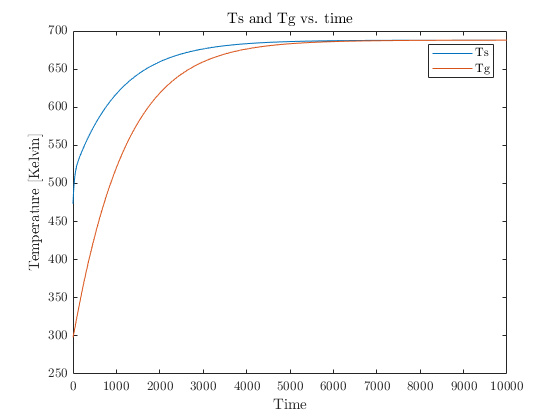

% Your solution goes here:


%The constants...
kc = 0.85; %Watt/deg.C
kg = 1.2;  %Watt/deg.C
kr = 7.8e-10; %Watt/K^4
Cs = 75;   %Joule/deg.C
Cg = 800;  %Joule/deg.C
k  = 100;  %Watt/volt
Ta = 298.15; %K
u0 = 5; %V
 
 % u0 is set to the constant value of 5 volt.
 % Ta is set to the constant value of 298.15 K.
 % Tsi is set to 473.15 K in the integrator initial condition 
 % Tgi is set to 298.15 K in the integrator initial condition 
 
 % After around 8000 seconds the temperature has stabilised. Tg becomes 688
 % K and Ts becomes 688 K... they are end up having the same value... wauw.
 
 sCon = 1; %setting sCon to 1 take the stepinput, setting sCon to 0 take the IN.
 sim('Q8')
 
 figure
 plot(Ts_out.time,Ts_out.signals.values ,Ts_out.time, Tg_out.signals.values)
 xlabel('Time');
 ylabel('Temperature [Kelvin]');
 title('Ts and Tg vs. time');
 legend('Ts', 'Tg');

**Problem 3**  Linearize the nonlinear Simulink model applying the Matlab function `linmod`. Use the function as follows

`[A,B,C,D] = linmod('modelname',x0,u0)`

where $x_0$ and $u_0$ are the stationary states and inputs.

Compare the result with that from the manual linearization from question "c'' in the Problem 2.10.

Find the eigenvalues of the $\mathbf{A}$ matrix by using the Matlab function `eig()`. Repeat the linearization for $u_0 = 2\,V$ and $u_0 = 8\,V$; $T_a = 10^{\circ}C$ and  $T_a = 35^{\circ}C$, and note how the linear model changes with the stationary state. Is the system stable, asymptotically stable or unstable in the different operating conditions?

Remove the radiation effect (set $k_r = 0$) and repeat the linearization for different values $u_0$.

**Solution****:**

% Your solution goes here:
sCon = 0;
x=Simulink.BlockDiagram.getInitialState('Q8');
[A,B,C,D]=linmod('Q8',x,u0)

A =      -0.03174        0.016
       0.0015      -0.0015


B =        1.3333
            0


C =      0     1


D =      0


[M,L] = eig(A)

M =      -0.99883     -0.45848
     0.048309      -0.8887


L =     -0.032514            0
            0  -0.00072615


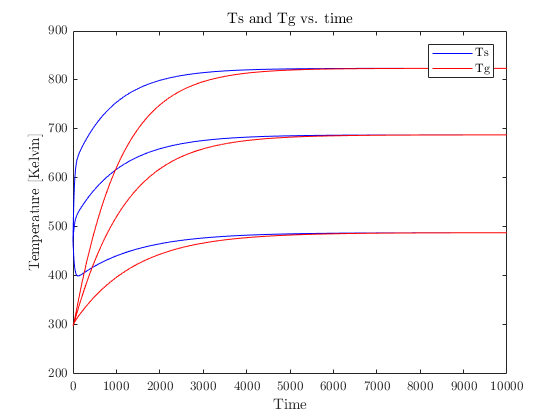

Ta1 = [308.15 298.15 283.15]; %K
uO = [2 5 8]; %V
 figure
  for i=1:3 
       u0=uO(i);
 sCon = 1; %setting sCon to 1 take the stepinput, setting sCon to 0 take the IN.
 sim('Q8')

     
  plot(Ts_out.time,Ts_out.signals.values,'b', Ts_out.time, Tg_out.signals.values,'r')
  hold on
 xlabel('Time');
 ylabel('Temperature [Kelvin]');
 title('Ts and Tg vs. time');
 legend('Ts', 'Tg');
 end